load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29



% Find missing data
sum(sum(ismissing(HCV)))

ans = 0

dat=HCV;

Binary and categorical outcomes -> classification problem

Continuous outcomes (values with a range) -> regression problem

% Exploratory data analysis
% Continuous -> histograms,boxplots of individual variables ; scatter plots of related variables
% Individual variables -> dat(:,[1,3,11:end])

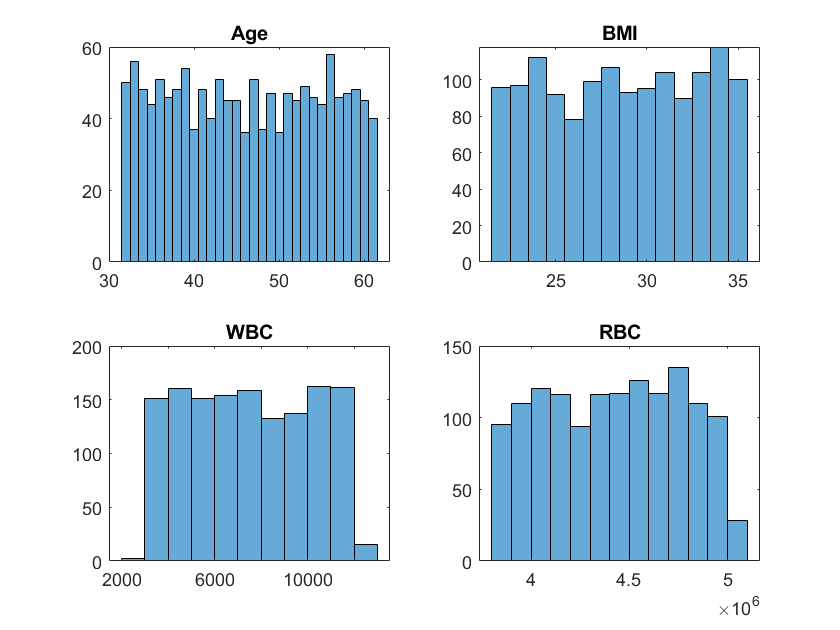

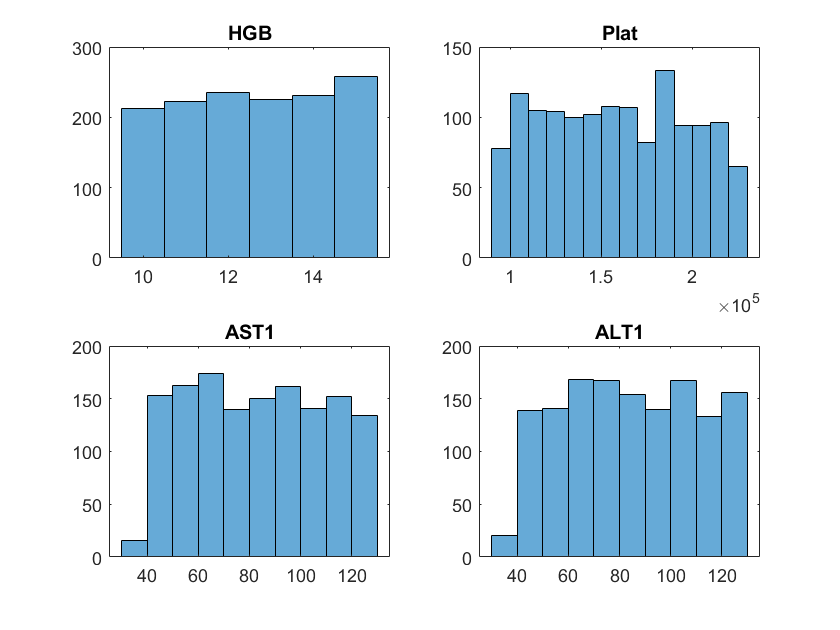

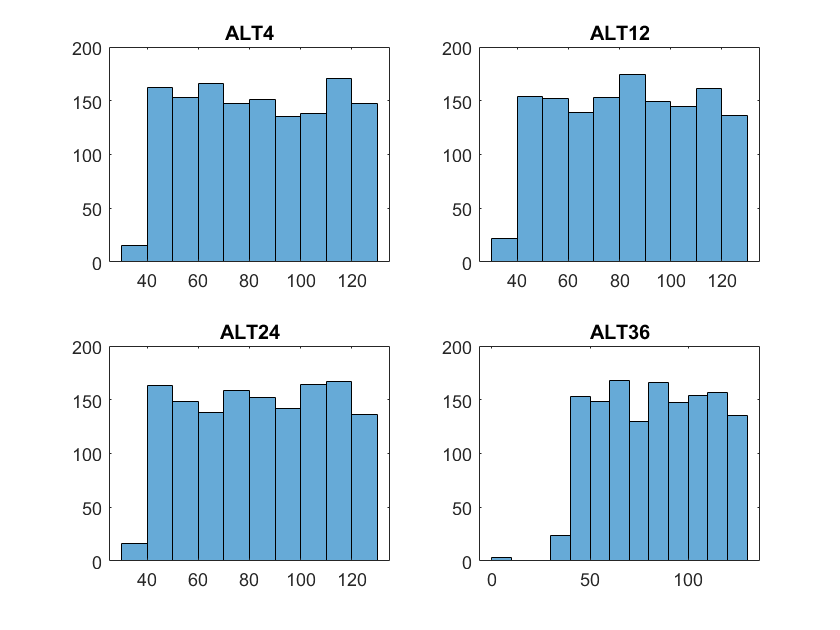

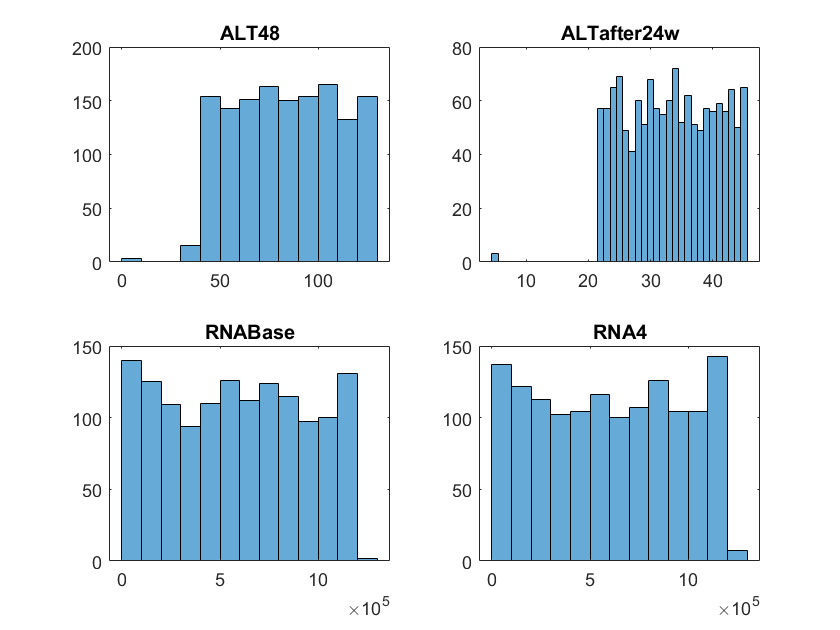

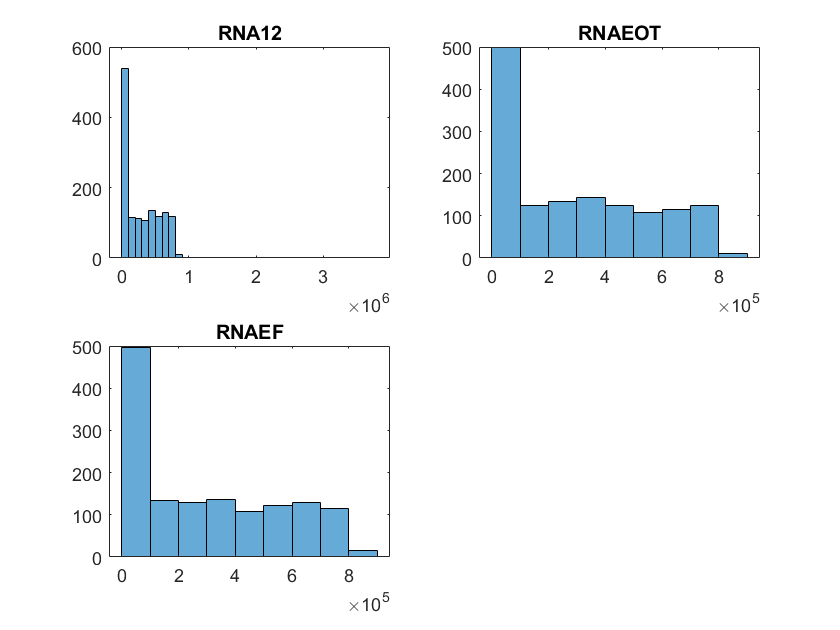

figure
k=0;
for i=[1,3,11:27]
    k=k+1;
    subplot(2,2,k)
    histogram(dat.(i))
    title(dat.Properties.VariableNames(i))
    if rem(k,4)==0
        k=0;
        figure
    end
end

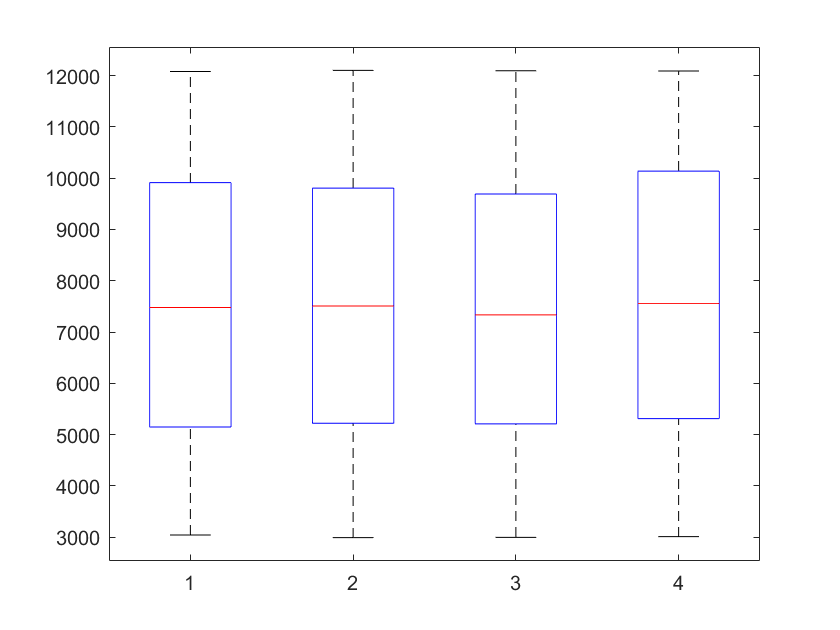

figure
boxplot(dat.WBC,dat.Baselinehistologicalstaging)

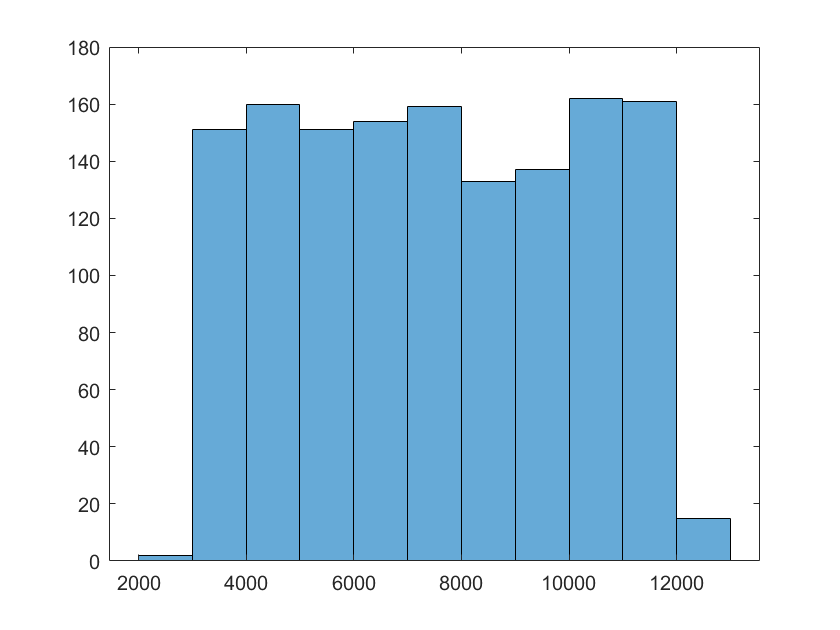

histogram(dat.WBC)

[N, edges,bin]=histcounts(dat.WBC)

N =      2   151   160   151   154   159   133   137   162   161    15


edges =         2000        3000        4000        5000        6000        7000        8000        9000       10000       11000       12000       13000


bin =      6
    11
     3
     5
     2
    10
    10
     6
     9
     5


sum(bin(bin==1))

ans = 2

sum(isoutlier(dat.WBC))

ans = 0

o1=find(bin==1)

o1 =    286
   590


b=dat.WBC

b =         7425
       12101
        4178
        6490
        3661
       11785
       11620
        7335
       10480
        6681


b([286,590],:)=[] % removed 2 outlier elements

b =         7425
       12101
        4178
        6490
        3661
       11785
       11620
        7335
       10480
        6681


o16=find(bin==11)

o16 =      2
   113
   115
   126
   218
   279
   511
   599
   628
   631


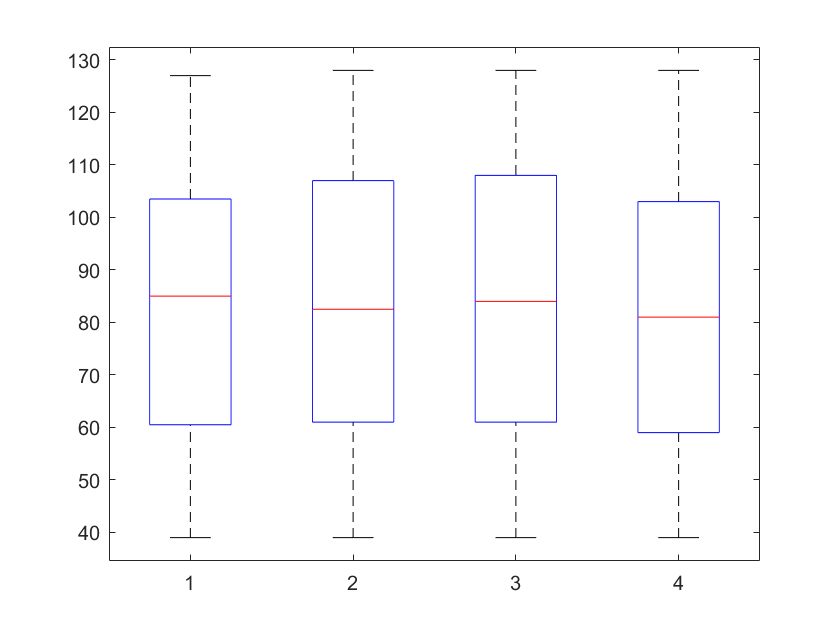

boxplot(dat.AST1,dat.Baselinehistologicalstaging)

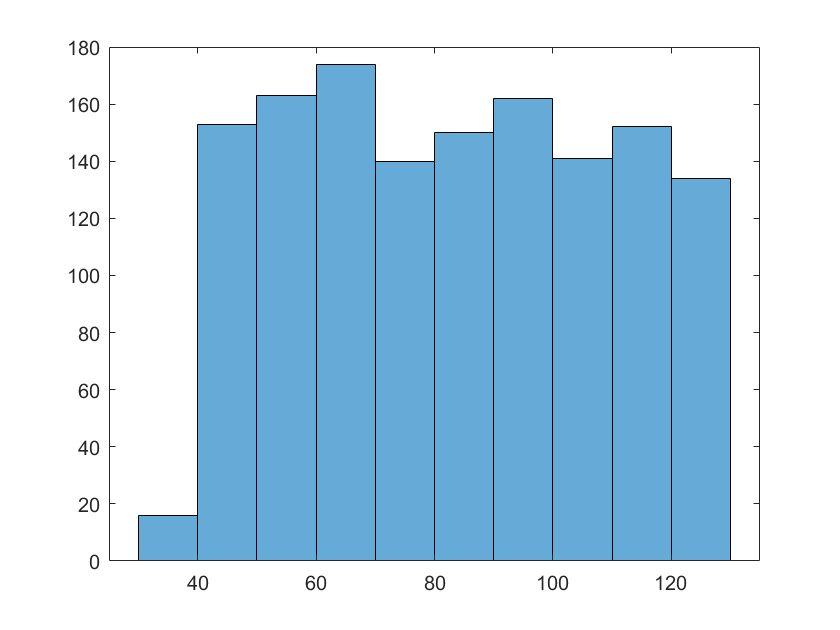

histogram(dat.AST1)

[N, edges,bin]=histcounts(dat.AST1) %16 elements in bin 1

N =     16   153   163   174   140   150   162   141   152   134


edges =     30    40    50    60    70    80    90   100   110   120   130


bin =      7
     7
     9
     2
     7
     4
     5
     9
     7
     3


o7=find(bin==1)

o7 =     76
   193
   400
   553
   602
   628
   668
   689
   735
   809


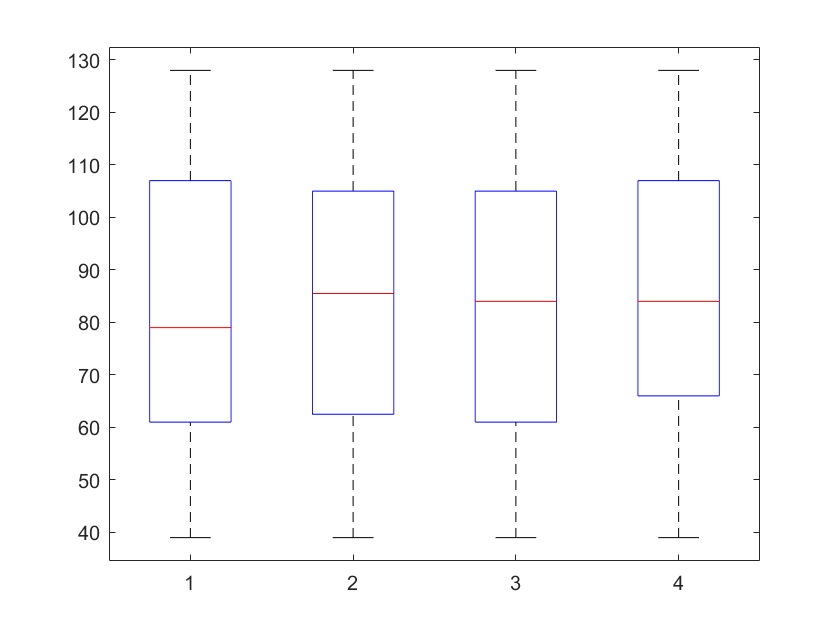


boxplot(dat.ALT1,dat.Baselinehistologicalstaging)

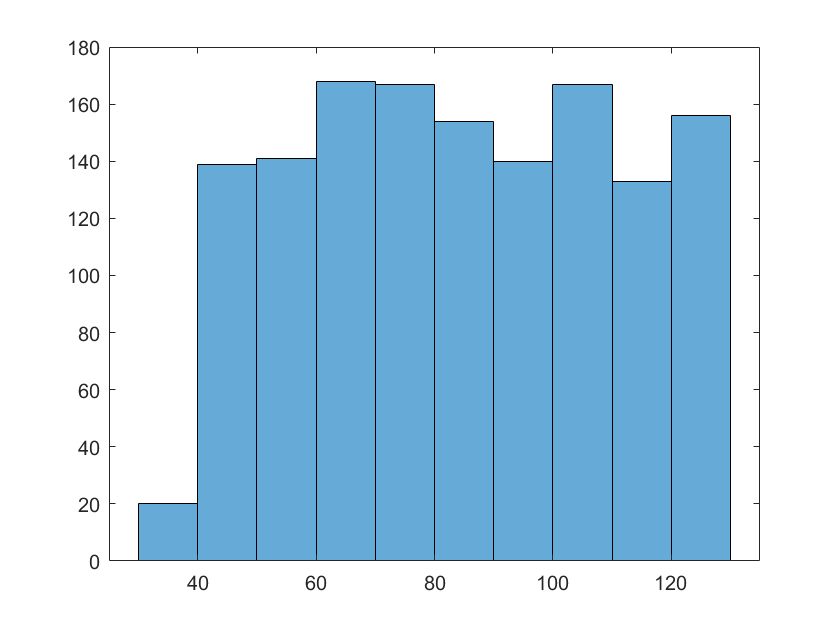

histogram(dat.ALT1)

[N, edges,bin]=histcounts(dat.ALT1) %20 elements in bin 1

N =     20   139   141   168   167   154   140   167   133   156


edges =     30    40    50    60    70    80    90   100   110   120   130


bin =      6
    10
     2
     4
     8
     8
     3
     9
     6
     4


o8=find(bin==1)

o8 =    116
   171
   204
   416
   502
   549
   696
   756
   787
   798


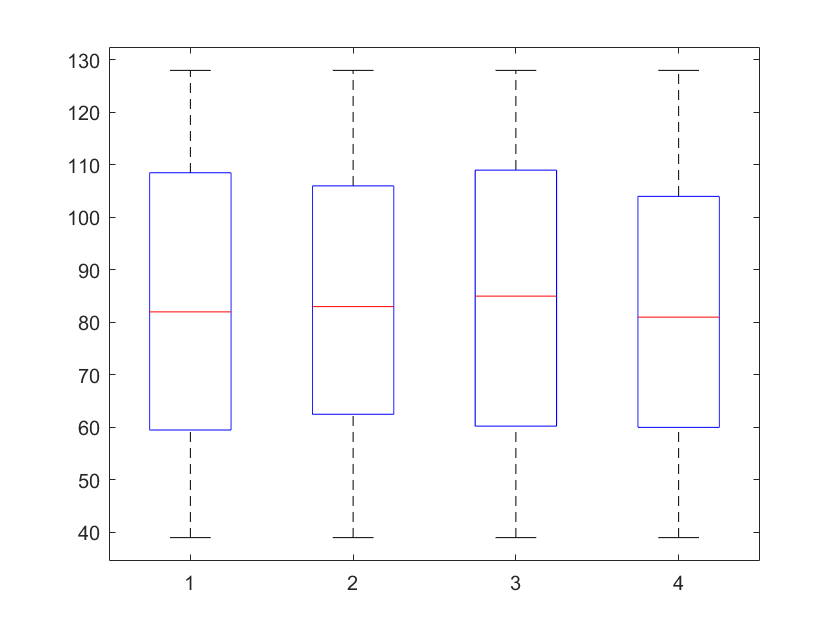


boxplot(dat.ALT4,dat.Baselinehistologicalstaging)

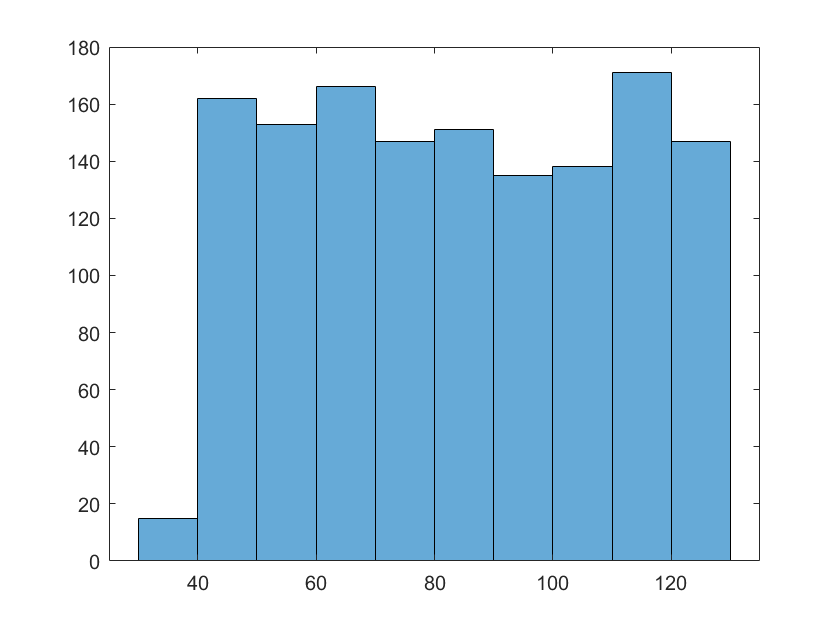

histogram(dat.ALT4)

[N, edges,bin]=histcounts(dat.ALT4) %15 elements in bin 1

N =     15   162   153   166   147   151   135   138   171   147


edges =     30    40    50    60    70    80    90   100   110   120   130


bin =      3
     7
     7
     8
     4
    10
     9
     6
     3
     5


o9=find(bin==1)

o9 =    116
   140
   154
   160
   167
   374
   700
   738
   748
   982


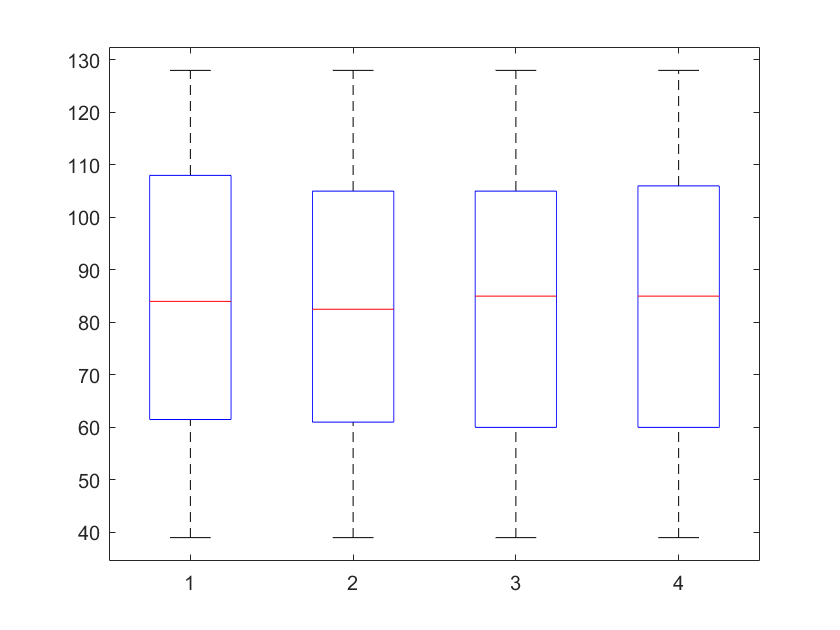


boxplot(dat.ALT12,dat.Baselinehistologicalstaging)

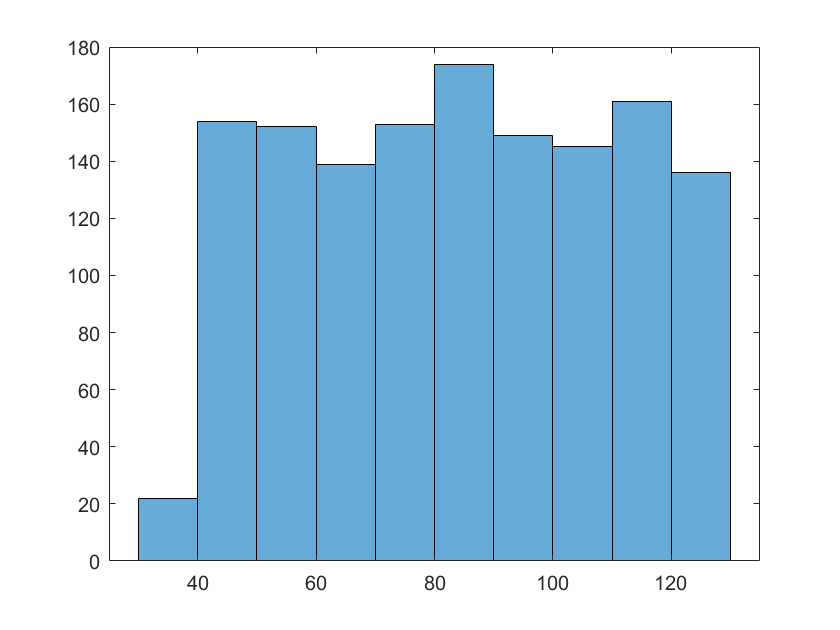

histogram(dat.ALT12)

[N, edges,bin]=histcounts(dat.ALT12) %22 elements in bin 1

N =     22   154   152   139   153   174   149   145   161   136


edges =     30    40    50    60    70    80    90   100   110   120   130


bin =      8
     5
     8
     6
     2
     7
     9
    10
     8
    10


o10=find(bin==1)

o10 =     91
   167
   195
   301
   353
   426
   486
   658
   739
   744


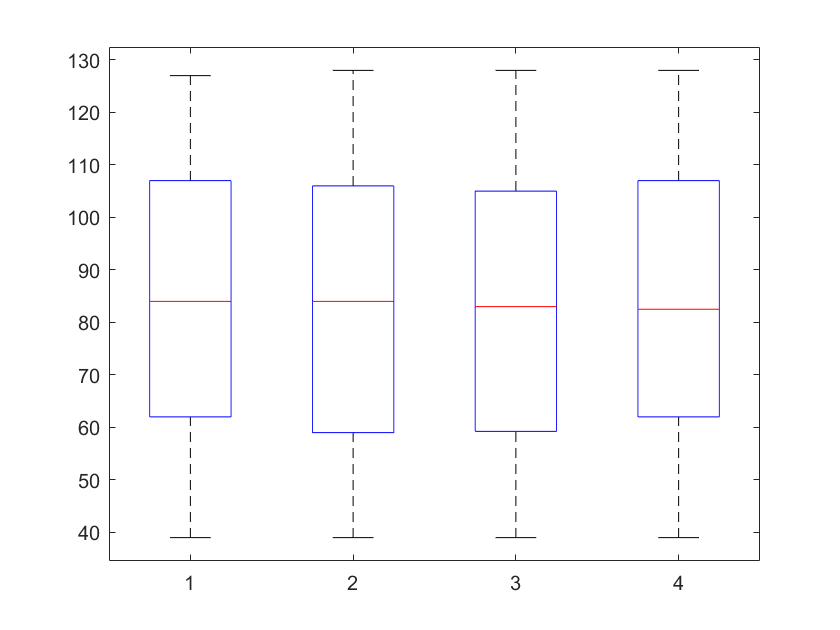


boxplot(dat.ALT24,dat.Baselinehistologicalstaging)

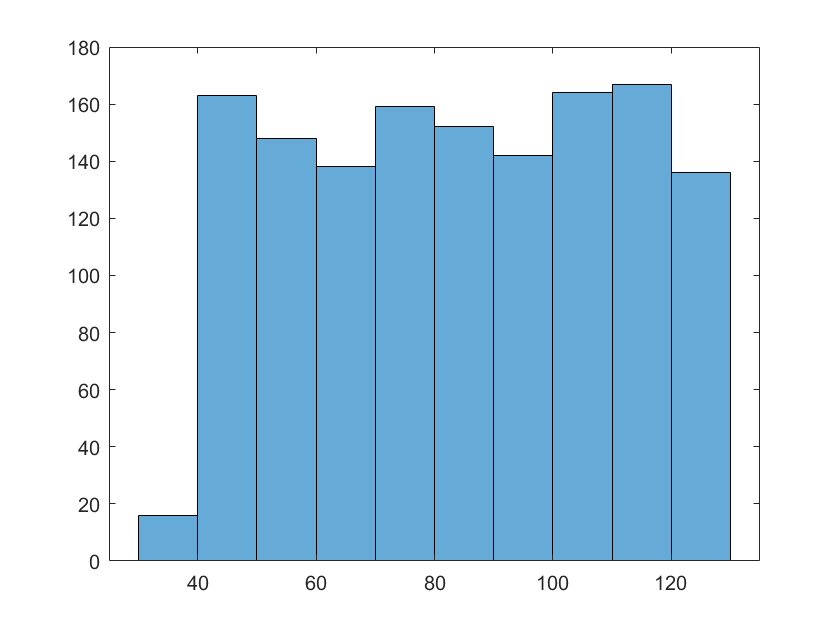

histogram(dat.ALT24)

[N, edges,bin]=histcounts(dat.ALT24) %16 elements in bin 1

N =     16   163   148   138   159   152   142   164   167   136


edges =     30    40    50    60    70    80    90   100   110   120   130


bin =      6
     9
     9
     6
    10
     4
     8
     2
     7
     6


o11=find(bin==1)

o11 =     56
   150
   182
   194
   198
   457
   461
   562
   616
   842


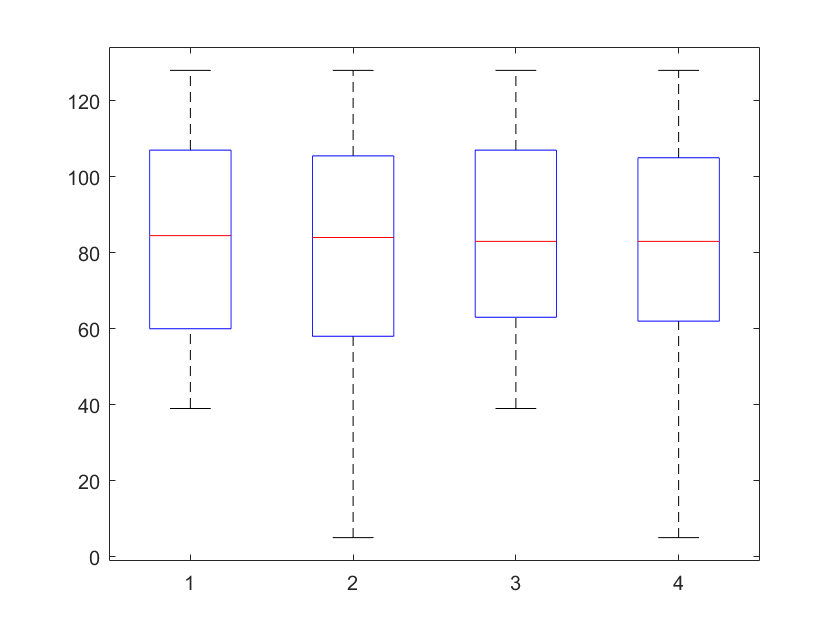

boxplot(dat.ALT36,dat.Baselinehistologicalstaging)

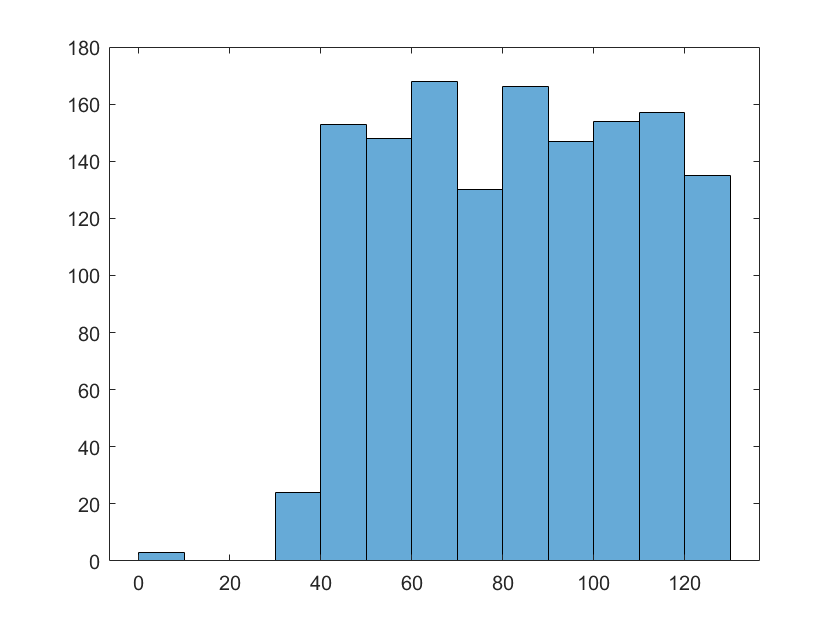

histogram(dat.ALT36)

[N, edges,bin]=histcounts(dat.ALT36)

N =      3     0     0    24   153   148   168   130   166   147   154   157   135


edges =      0    10    20    30    40    50    60    70    80    90   100   110   120   130


bin =      1
     6
     1
     5
    10
     8
     9
    10
    13
    13


o2=find(bin==1)

o2 =      1
     3
   458


sum(isoutlier(dat.ALT36)) % doesnt show the 3 outliers

ans = 0

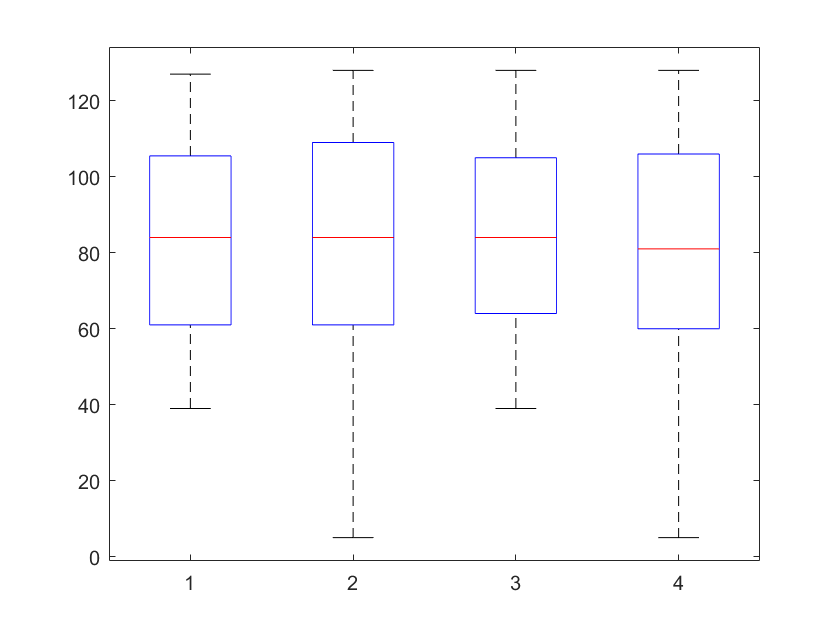

boxplot(dat.ALT48,dat.Baselinehistologicalstaging)

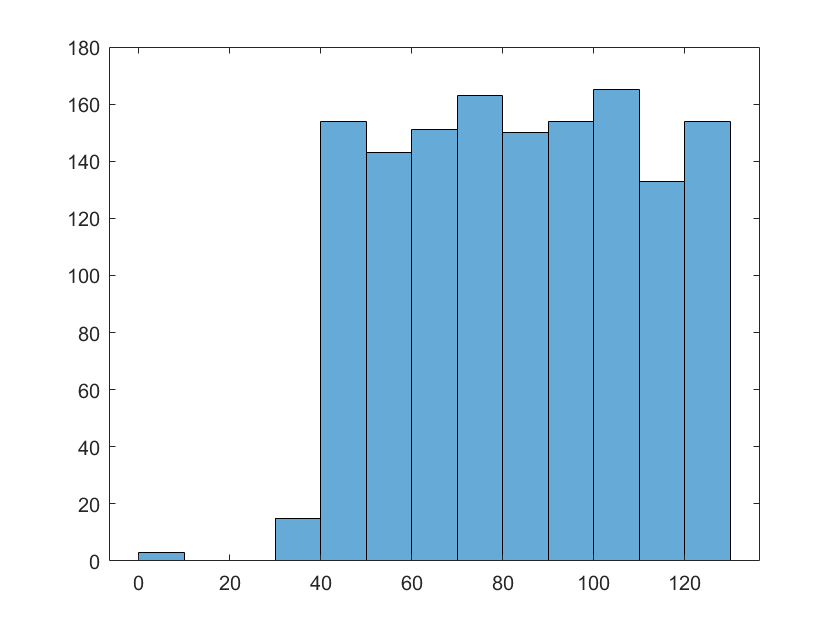

histogram(dat.ALT48)

[N, edges,bin]=histcounts(dat.ALT48)

N =      3     0     0    15   154   143   151   163   150   154   165   133   154


edges =      0    10    20    30    40    50    60    70    80    90   100   110   120   130


bin =      1
    13
     1
     8
    10
    12
     9
     6
     4
     5


o3=find(bin==1)

o3 =      1
     3
   458


sum(isoutlier(dat.ALT48))%doesnt show the 3 outliers

ans = 0

o17=find(bin==4)

o17 =      9
    88
   108
   158
   241
   316
   372
   467
   468
   471


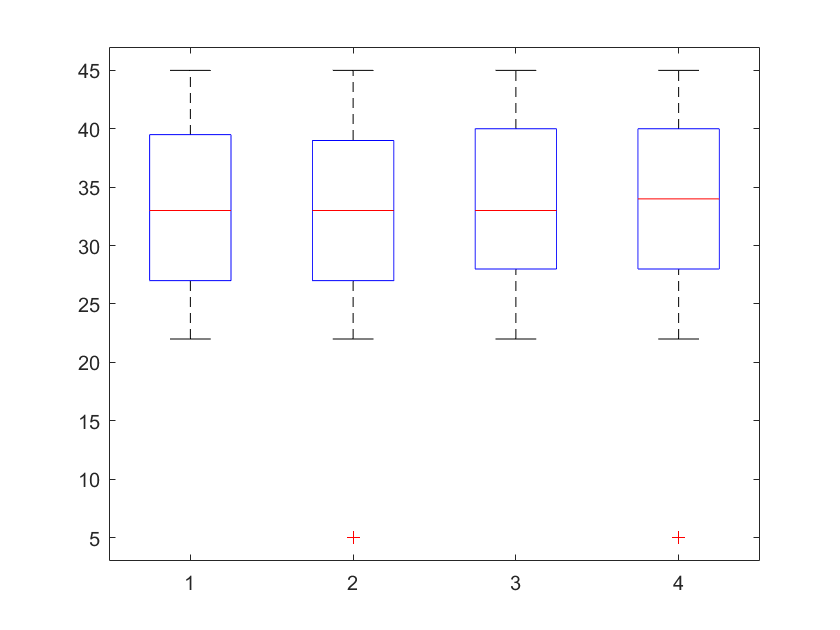

boxplot(dat.ALTafter24w,dat.Baselinehistologicalstaging)

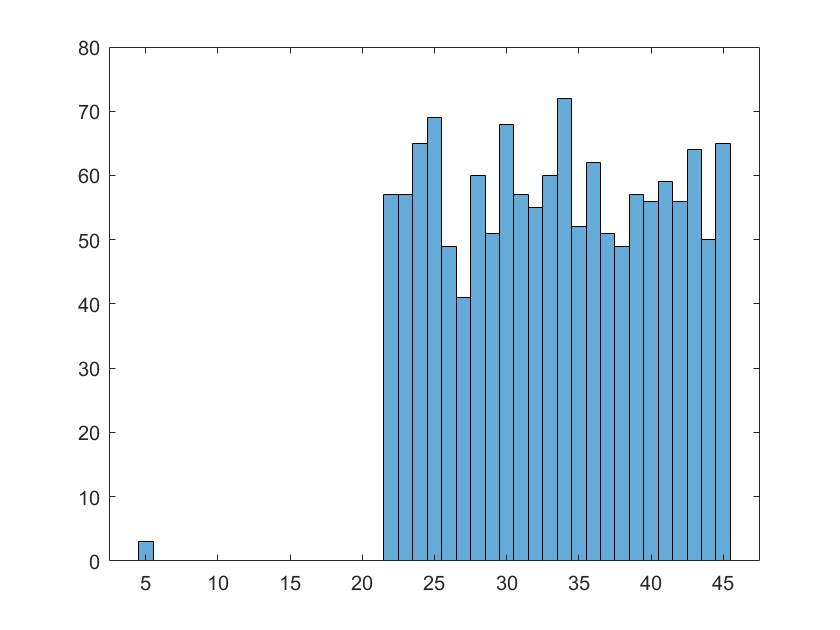

histogram(dat.ALTafter24w)

[N, edges,bin]=histcounts(dat.ALTafter24w) % Bin 1 has 3 elements

N =      3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    57    57    65    69    49    41    60    51    68    57    55    60    72    52    62    51    49    57    56    59    56    64    50    65


edges =     4.5000    5.5000    6.5000    7.5000    8.5000    9.5000   10.5000   11.5000   12.5000   13.5000   14.5000   15.5000   16.5000   17.5000   18.5000   19.5000   20.5000   21.5000   22.5000   23.5000   24.5000   25.5000   26.5000   27.5000   28.5000   29.5000   30.5000   31.5000   32.5000   33.5000   34.5000   35.5000   36.5000   37.5000   38.5000   39.5000   40.5000   41.5000   42.5000   43.5000   44.5000   45.5000


bin =      1
    40
     1
    29
    26
    25
    24
    35
    41
    26


o4=find(bin==1)

o4 =      1
     3
   458


sum(isoutlier(dat.ALTafter24w))

ans = 3

a=rmoutliers(dat.ALTafter24w)

a =     44
    33
    30
    29
    28
    39
    45
    30
    33
    45


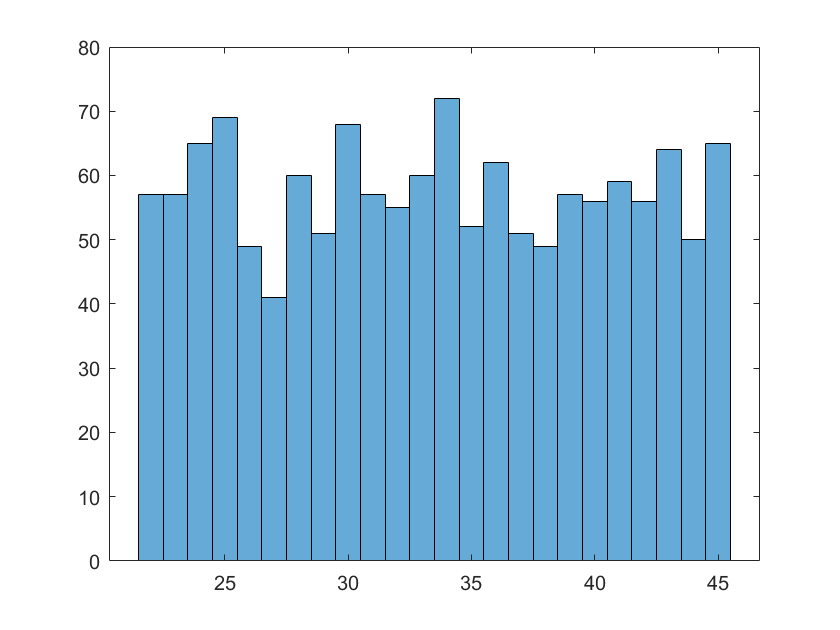

histogram(a)

[N, edges,bin]=histcounts(a)

N =     57    57    65    69    49    41    60    51    68    57    55    60    72    52    62    51    49    57    56    59    56    64    50    65


edges =    21.5000   22.5000   23.5000   24.5000   25.5000   26.5000   27.5000   28.5000   29.5000   30.5000   31.5000   32.5000   33.5000   34.5000   35.5000   36.5000   37.5000   38.5000   39.5000   40.5000   41.5000   42.5000   43.5000   44.5000   45.5000


bin =     23
    12
     9
     8
     7
    18
    24
     9
    12
    24


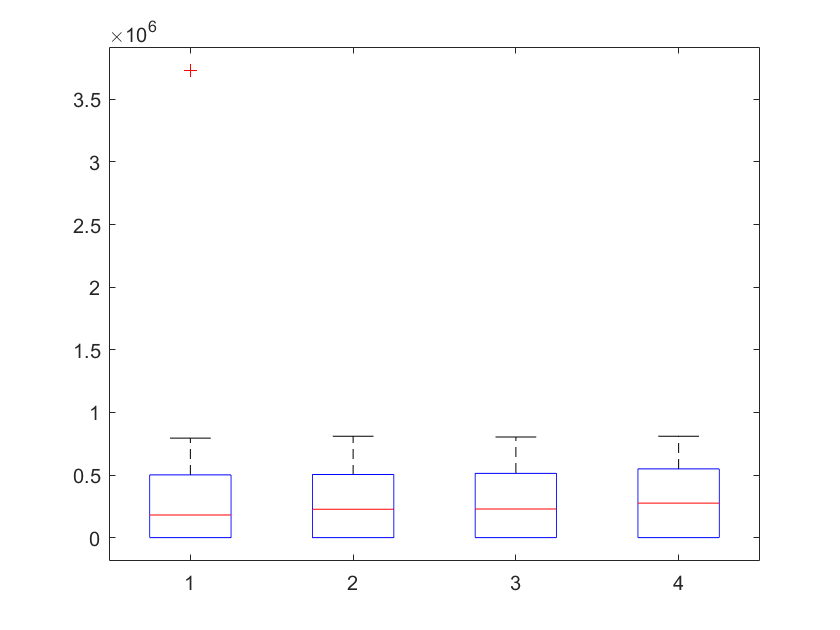


boxplot(dat.RNA12,dat.Baselinehistologicalstaging)

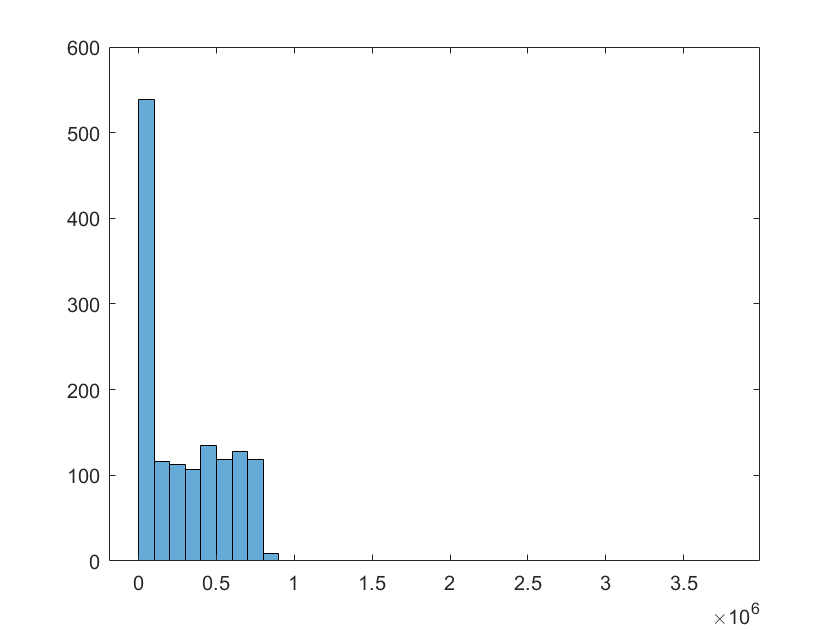

histogram(dat.RNA12)

[N, edges,bin]=histcounts(dat.RNA12) % Bin 38 has 1 element

N =    539   116   113   107   135   119   128   118     9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1


edges =            0      100000      200000      300000      400000      500000      600000      700000      800000      900000     1000000     1100000     1200000     1300000     1400000     1500000     1600000     1700000     1800000     1900000     2000000     2100000     2200000     2300000     2400000     2500000     2600000     2700000     2800000     2900000     3000000     3100000     3200000     3300000     3400000     3500000     3600000     3700000     3800000


bin =      3
     7
     1
     6
    38
     1
     3
     8
     1
     3


o5=find(bin==38)

o5 = 5

sum(isoutlier(dat.RNA12,'quartiles'))

ans = 1

a=rmoutliers(dat.RNA12) %remove bin 38 element

a =       288194
      637056
           5
      585688
           5
      275095
      787295
           5
      267320
      731929


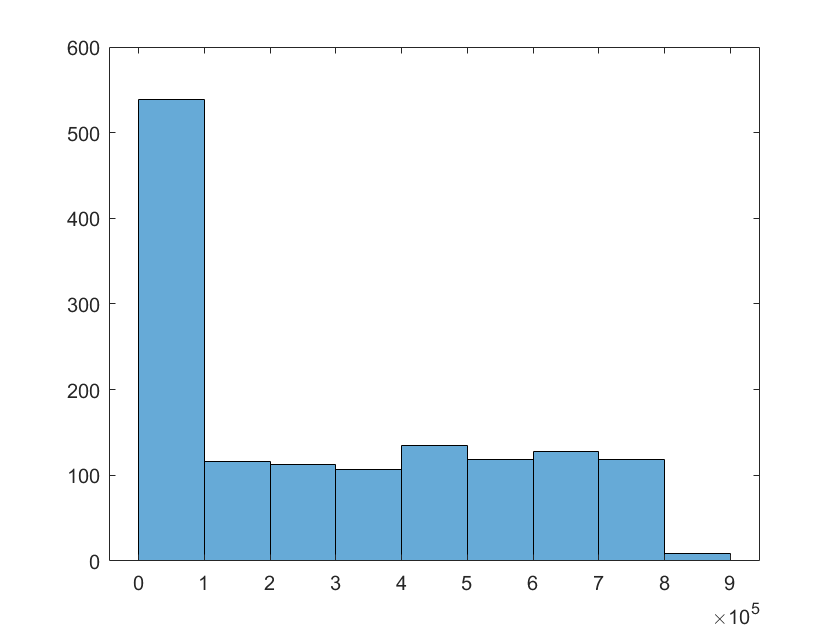

histogram(a)

[N, edges,bin]=histcounts(a) % Think about bin 9 with 9 elements

N =    539   116   113   107   135   119   128   118     9


edges =            0      100000      200000      300000      400000      500000      600000      700000      800000      900000


bin =      3
     7
     1
     6
     1
     3
     8
     1
     3
     8


o12=find(bin==9)

o12 =          327
         395
         499
         625
         864
        1213
        1317
        1375
        1382


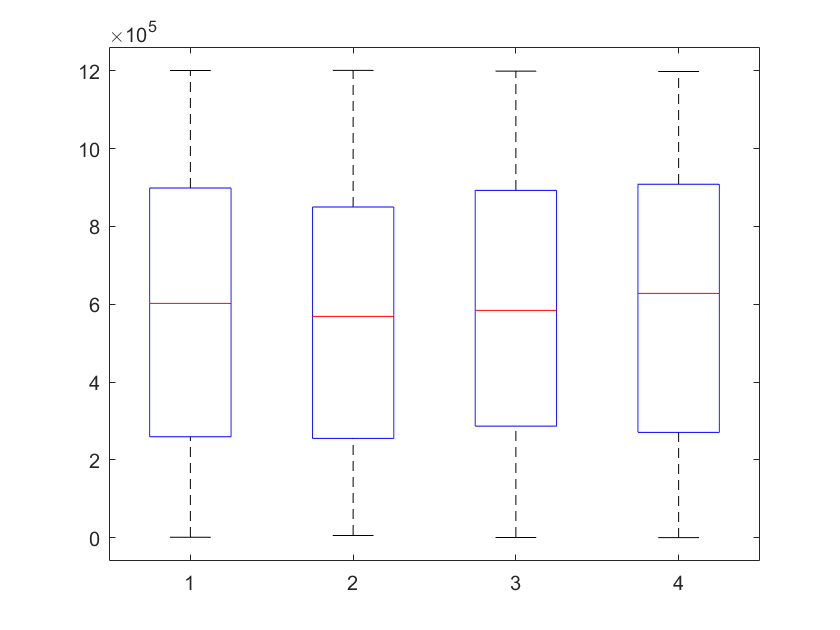

boxplot(dat.RNABase,dat.Baselinehistologicalstaging)

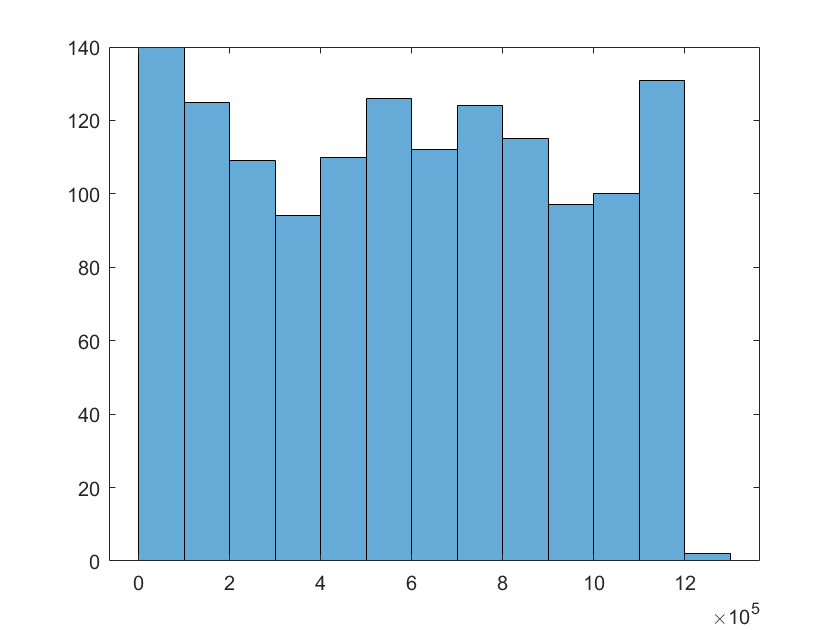

histogram(dat.RNABase)

[N, edges,bin]=histcounts(dat.RNABase) %bin13 2 elements think

N =    140   125   109    94   110   126   112   124   115    97   100   131     2


edges =            0      100000      200000      300000      400000      500000      600000      700000      800000      900000     1000000     1100000     1200000     1300000


bin =      7
     1
     6
    11
     7
    12
     4
     7
     6
    12


o6=find(bin==13)

o6 =          119
        1018


sum(isoutlier(dat.RNABase))

ans = 0

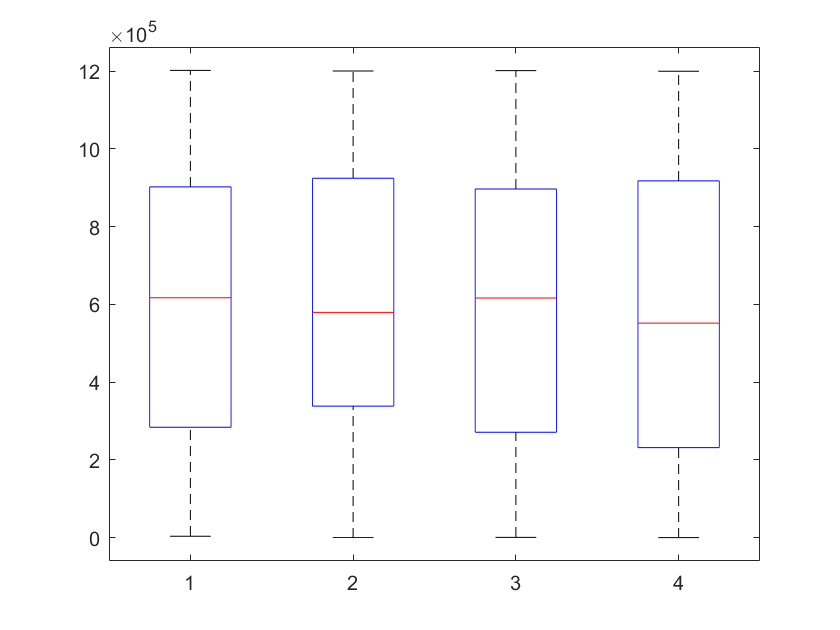


boxplot(dat.RNA4,dat.Baselinehistologicalstaging)

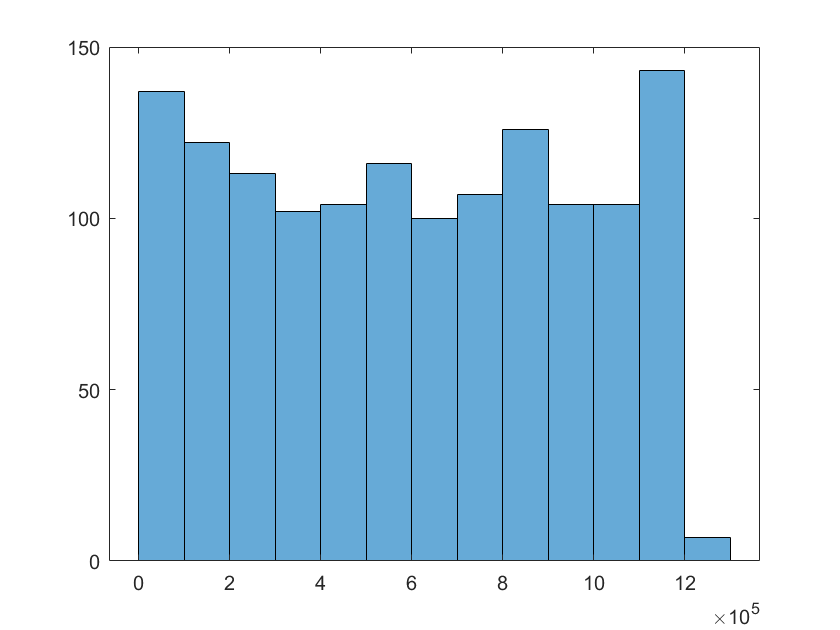

histogram(dat.RNA4)

[N, edges,bin]=histcounts(dat.RNA4)%bin13 7 elements think

N =    137   122   113   102   104   116   100   107   126   104   104   143     7


edges =            0      100000      200000      300000      400000      500000      600000      700000      800000      900000     1000000     1100000     1200000     1300000


bin =      7
     6
     7
     5
     8
    11
    11
     1
     8
     3


o13=find(bin==13)

o13 =          254
         301
         444
         484
         625
        1037
        1353


sum(isoutlier(dat.RNA4))

ans = 0

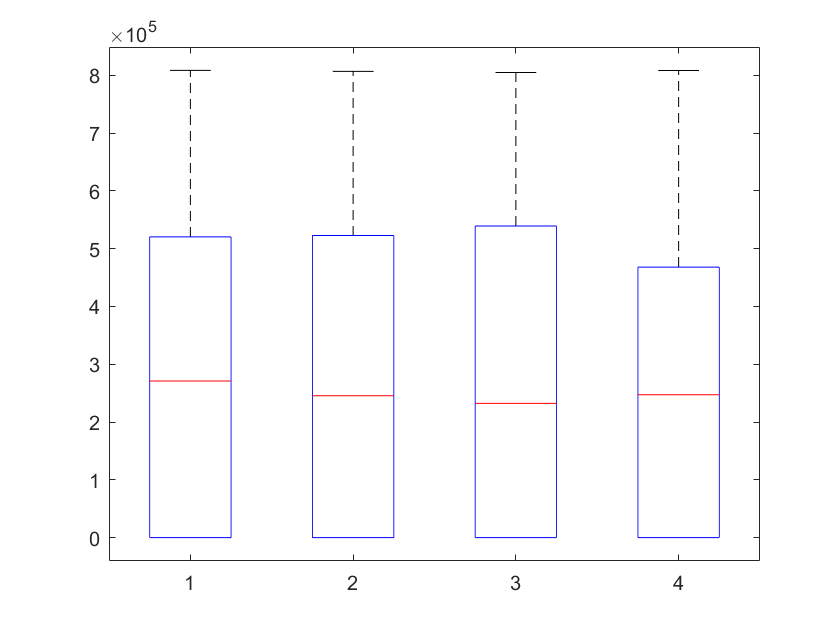


boxplot(dat.RNAEOT,dat.Baselinehistologicalstaging)

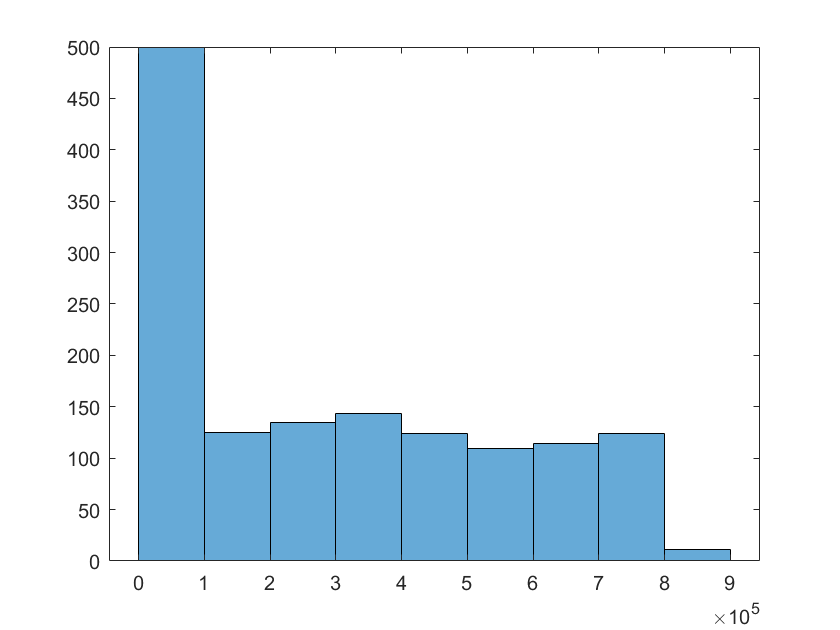

histogram(dat.RNAEOT)

[N, edges,bin]=histcounts(dat.RNAEOT)%bin9 11 elements think

N =    500   125   135   143   124   109   114   124    11


edges =            0      100000      200000      300000      400000      500000      600000      700000      800000      900000


bin =      1
     4
     8
     8
     4
     1
     3
     4
     4
     3


o14=find(bin==9)

o14 =          115
         297
         311
         362
         425
         615
         635
         818
        1054
        1218


sum(isoutlier(dat.RNAEOT))

ans = 0

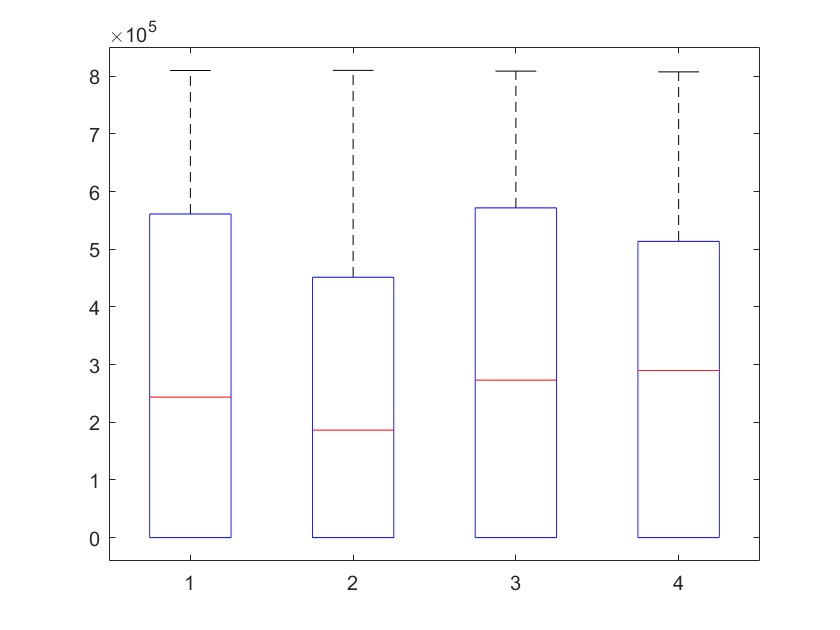

boxplot(dat.RNAEF,dat.Baselinehistologicalstaging)

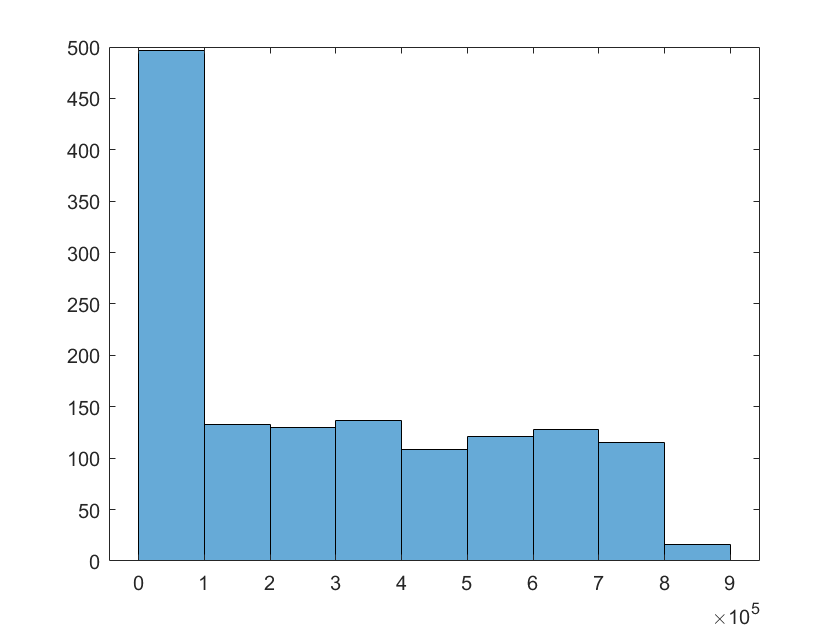

histogram(dat.RNAEF)

[N, edges,bin]=histcounts(dat.RNAEF)%bin9 16 elements think

N =    497   133   130   137   108   121   128   115    16


edges =            0      100000      200000      300000      400000      500000      600000      700000      800000      900000


bin =      1
     1
     6
     6
     3
     1
     7
     6
     3
     6


o15=find(bin==9)

o15 =     12
   112
   235
   283
   321
   342
   349
   409
   520
   557


sum(isoutlier(dat.RNAEF))

ans = 0

[N, edges,bin]=histcounts(dat.Baselinehistologicalstaging) % Each stage has around 330-365 elements

N =    336   332   355   362


edges =     0.5000    1.5000    2.5000    3.5000    4.5000


bin =      2
     2
     4
     3
     1
     4
     4
     3
     2
     2



outlier_indices=unique([o1;o2;o3;o4;o5;o6])

outlier_indices =            1
           3
           5
         119
         286
         458
         590
        1018


%dat([outlier_indices],'Baselinehistologicalstaging')
fram=dat;
size(fram)

ans =         1385          29


fram([outlier_indices],:)=[];
size(fram)

ans =         1377          29


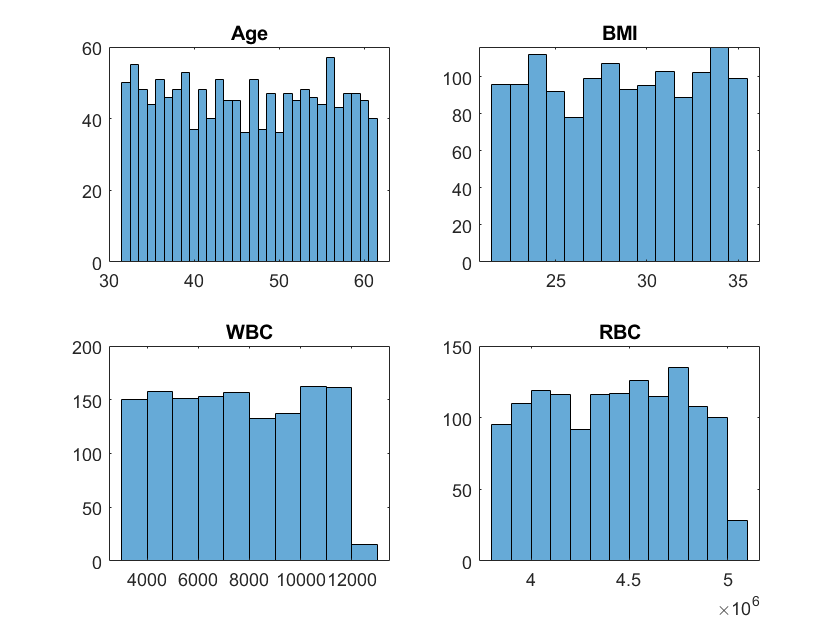

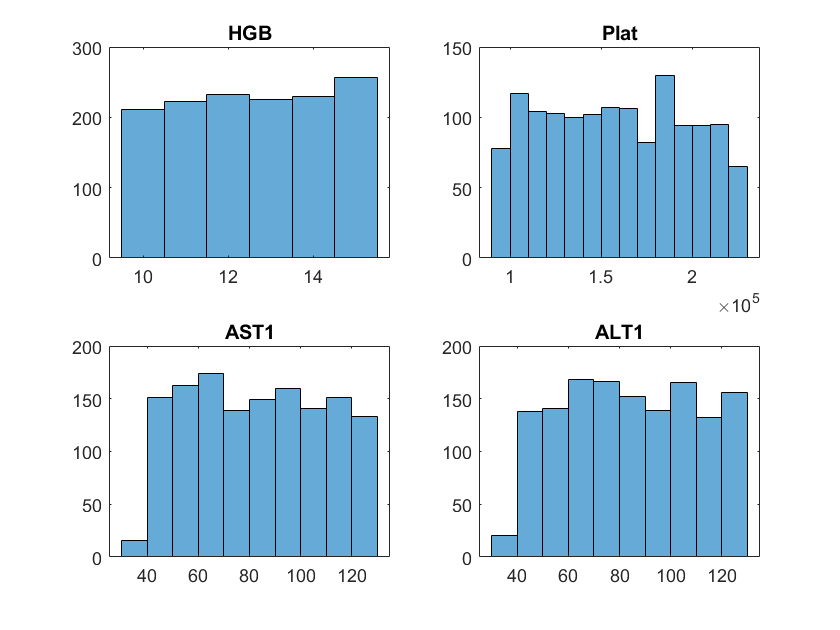

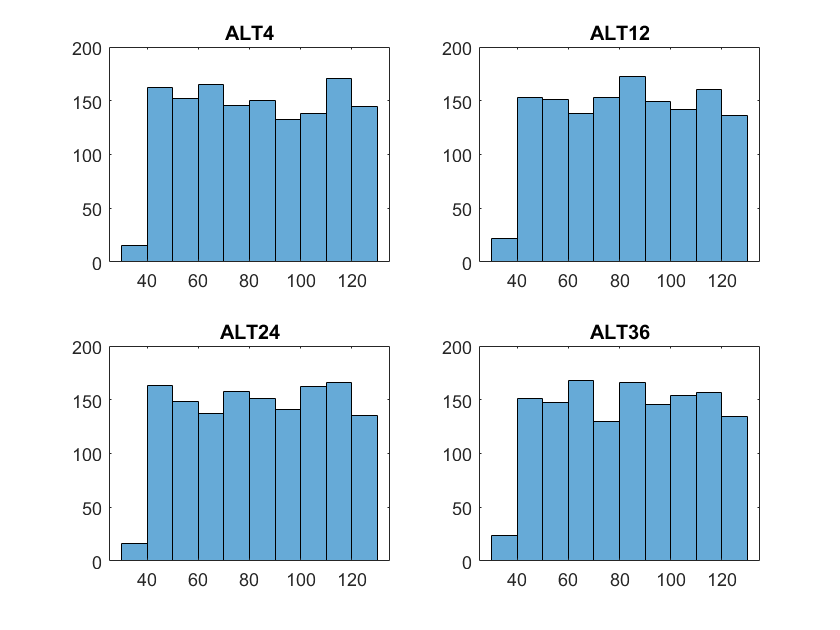

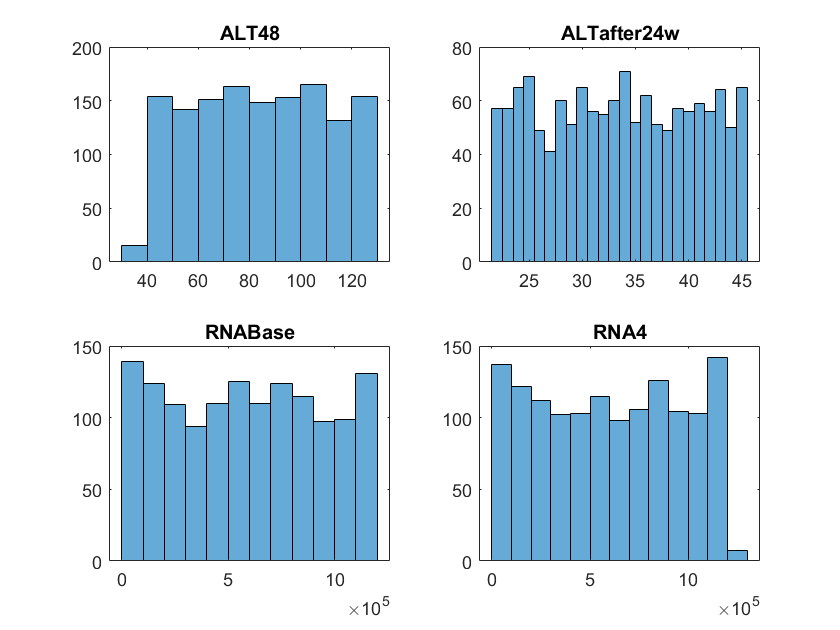

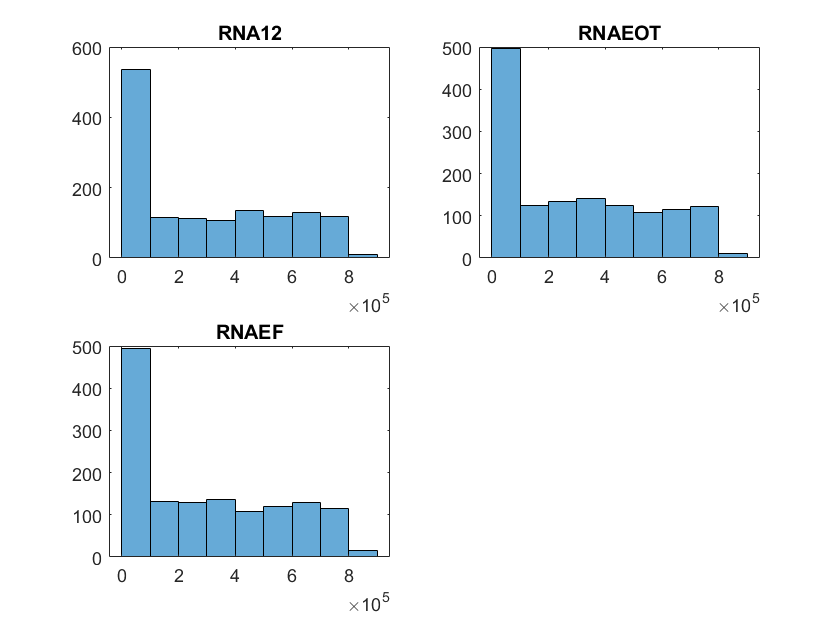


% Minimal outliers removed
figure
k=0;
for i=[1,3,11:27]
    k=k+1;
    subplot(2,2,k)
    histogram(fram.(i))
    title(fram.Properties.VariableNames(i))
    if rem(k,4)==0
        k=0;
        figure
    end
end

outlier_indices_more=unique([o1;o2;o3;o4;o5;o6;o7;o8;o9;o10;o11;o12;o13;o14;o15;o16;o17])

outlier_indices_more =      1
     2
     3
     5
     9
    12
    56
    76
    88
    91


dat([outlier_indices_more],'Baselinehistologicalstaging')

ans = 161×1 table
    Baselinehistologicalstaging
    ___________________________

                 2             
                 2             
                 4             
                 1             
                 2             
                 1             
                 2             
                 1             
                 4             
                 2             
                 2             
                 3             
                 1             
                 3             
                 4             
                 1             


fram1=dat;
size(fram1)

ans =         1385          29


fram1([outlier_indices_more],:)=[];
size(fram1)

ans =         1224          29


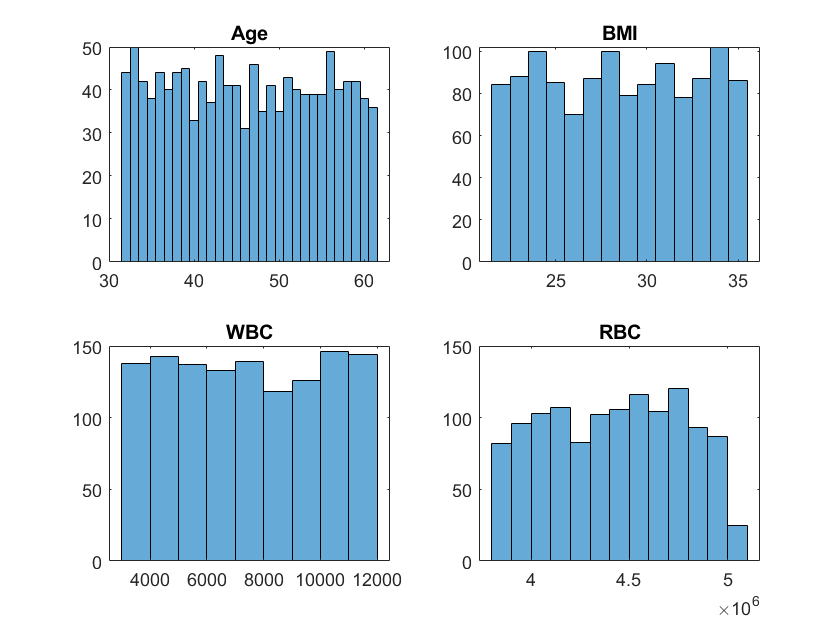

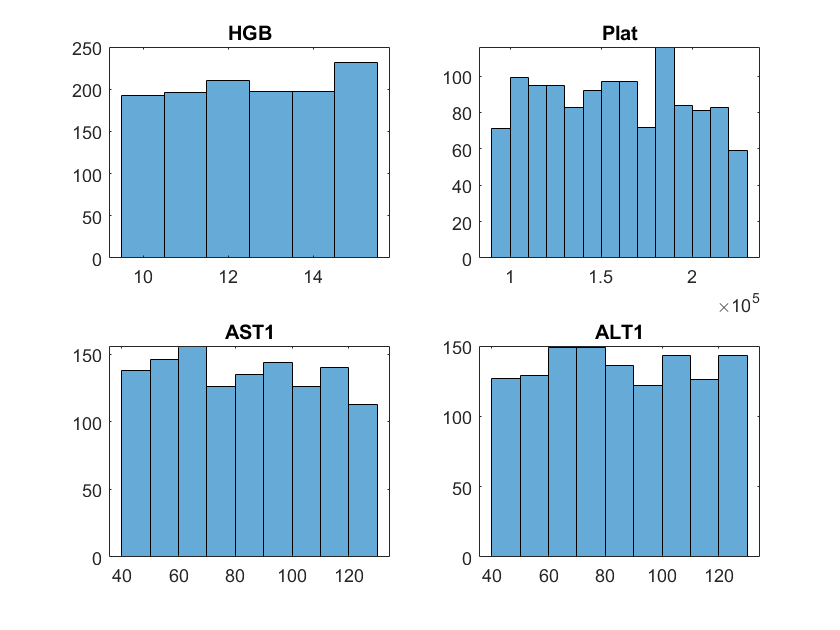

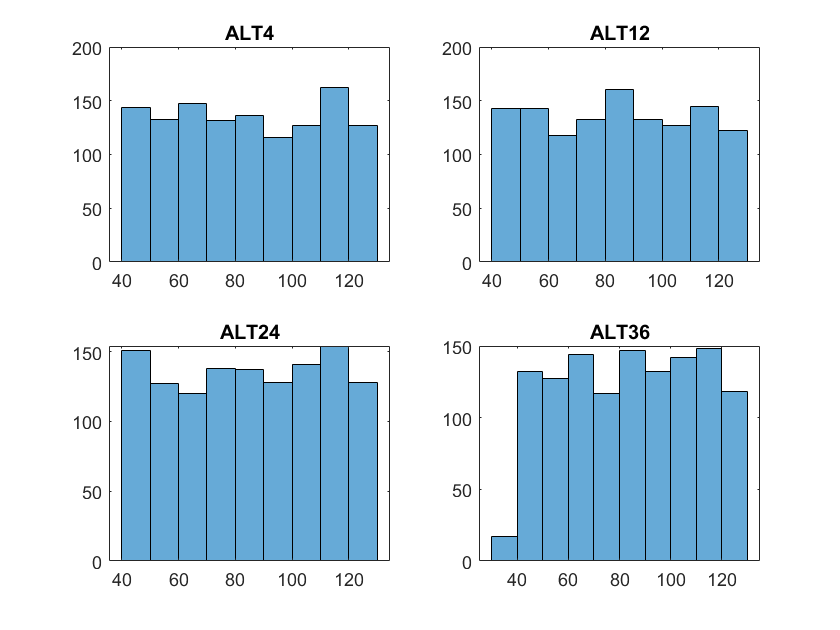

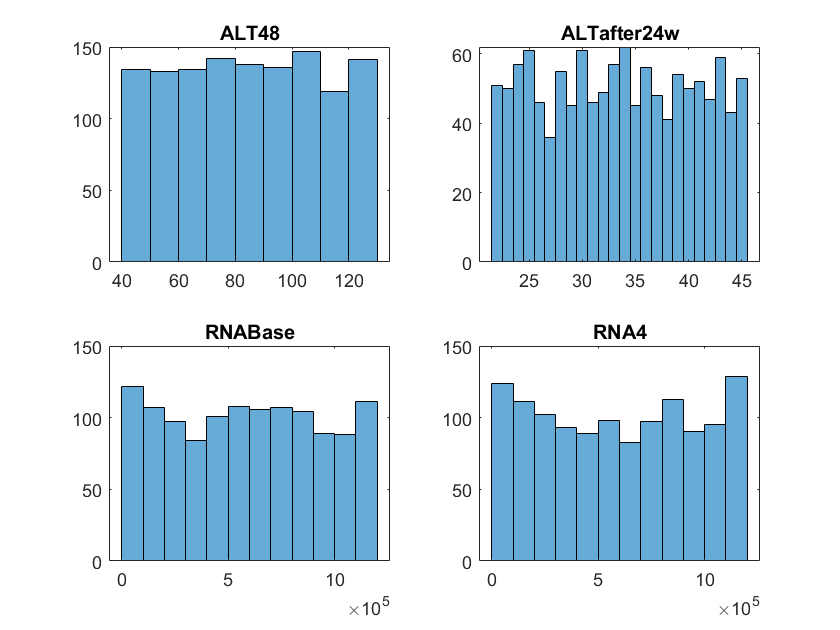

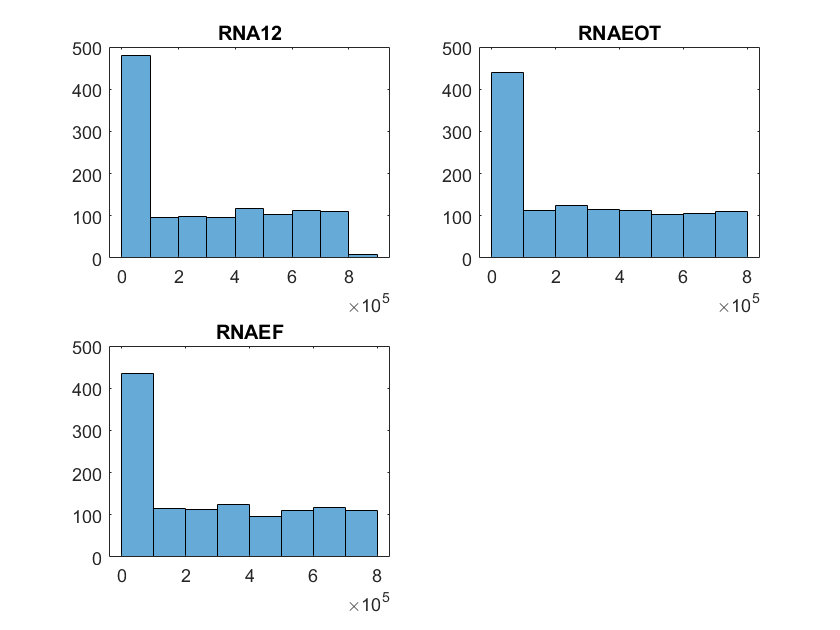


%Maximum outliers removed
figure
k=0;
for i=[1,3,11:27]
    k=k+1;
    subplot(2,2,k)
    histogram(fram1.(i))
    title(fram1.Properties.VariableNames(i))
    if rem(k,4)==0
        k=0;
        figure
    end
end

Stage

fram_array = table2array(fram);
corr(fram_array(:,[1,3,11:27]),fram_array(:,29))

ans =    -0.0155
   -0.0564
    0.0165
    0.0107
    0.0056
   -0.0160
   -0.0250
    0.0408
   -0.0142
   -0.0013


t1=array2table(corr(fram_array(:,1:27),fram_array(:,29)),"RowNames",dat.Properties.VariableNames(1:27));
k=zeros(sum(t1.Var1>0),1);
stagedat=zeros(length(fram_array),sum(t1.Var1>0));
l=0;
for i=1:27
    if t1.Var1(i)>0
        l=l+1;
        stagedat(:,l)=fram_array(:,i);
        k(l)=i;
    end
end
stagedat

stagedat =            1           2           2           2       12101     4429425          10         123          44       40620      637056       31085
           2           2           1           2        6490     4794631          10          64          33     1041941      585688      582301
           2           2           2           2       11785     3882456          15         104          29     1157452           5           5
           2           1           2           2       11620     4747333          12          57          28      325694      275095      635157
           2           1           1           1        7335     4405941          11         112          39      641129      787295      506296
           1           1           2           1       10480     4608464          12          83          45      591441           5      203042
           1           1           1           1        6681     4455329          12          68          30     115120

t1=sortrows(t1,'Var1','descend')

t1 = 27×1 table
                                     Var1   
                                  __________

    NauseaVomting                   0.053182
    RNA12                           0.051501
    ALT1                            0.040811
    ALTafter24w                      0.04003
    RNABase                         0.032465
    RNAEF                           0.030352
    Jaundice                        0.023574
    Fatiguegeneralizedboneache       0.01988
    WBC                             0.016524
    Gender                          0.012691
    RBC                              0.01073
    HGB                            0.0055596
    ALT12                         -0.0013476
    Headache                      -0

x=stagedat;
y=categorical(fram_array(:,29));
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(x,y,0.7);
RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [964x12]
                    Training Y:              [964x1]
                        Method:       classification
                 NumPredictors:                   12
         NumPredictorsToSample:                    4
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


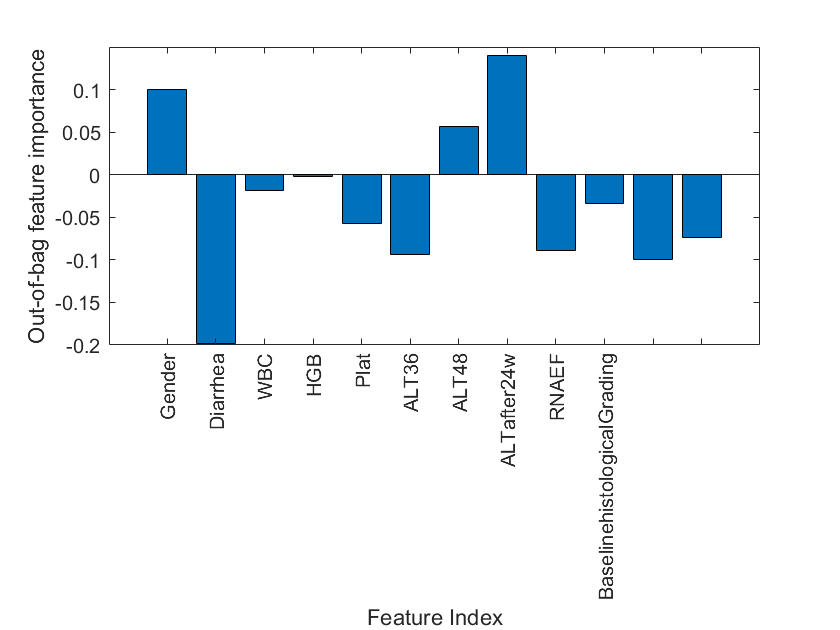

bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('Out-of-bag feature importance')
xticklabels(new_data.Properties.VariableNames(1:end))
xtickangle(90)

Ypred=predict(RFmodel,Xtest1) % RF gives output in cell array format

Ypred = 413×1 cell array
    {'3'}
    {'4'}
    {'4'}
    {'4'}
    {'2'}
    {'4'}
    {'3'}
    {'4'}
    {'4'}
    {'3'}
    {'3'}
    {'4'}
    {'2'}
    {'3'}
    {'3'}
    {'4'}
    {'3'}
    {'4'}
    {'1'}
    {'3'}
    {'4'}
    {'4'}
    {'2'}
    {'3'}
    {'2'}
    {'4'}
    {'2'}
    {'3'}
    {'4'}
    {'4'}


Ypred=categorical(Ypred) % cell array to categorical array

Ypred = 413×1 categorical array
     3 
     4 
     4 
     4 
     2 
     4 
     3 
     4 
     4 
     3 
     3 
     4 
     2 
     3 
     3 
     4 
     3 
     4 
     1 
     3 
     4 
     4 
     2 
     3 
     2 
     4 
     2 
     3 
     4 
     4 


sum(Ypred==Ytest1)/length(Ytest1) % accuracy

ans = 0.2760

confusionmat(double(Ytest1),double(Ypred))

Class List in given sample
     1
     2
     3
     4


Total Instance = 413
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          18                23                29                35      
    Actual_class2          15                18                26                44      
    Actual_class3          26                11                38                35      
    Actual_class4          11                15                29                40      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     18    23    29    35
    15    18    26    44
    26    11    38    35
    11    15    29    40


Grade

t2=array2table(corr(fram_array(:,1:27),fram_array(:,28)),"RowNames",dat.Properties.VariableNames(1:27));
k=zeros(sum(t2.Var1>0),1);
gradedat=zeros(length(fram_array),sum(t2.Var1>0));
l=0;
for i=1:27
    if t2.Var1(i)>0
        l=l+1;
        gradedat(:,l)=fram_array(:,i);
        k(l)=i;
    end
end
gradedat

gradedat =            1           1       12101          10      129367          57         123          44       31085
           2           2        6490          10      146457          48          77          33      582301
           2           1       11785          15      131228          73         114          29           5
           2           2       11620          12      177261          84          80          28      635157
           2           2        7335          11      216176          96          53          39      506296
           1           2       10480          12      148889         122          39          45      203042
           1           2        6681          12       98200         125          43          30      555516
           2           1        4437          12      166027         123         101          33       59998
           1           1        6052          13      144266          46          59          45      806204
        

t2=sortrows(t2,'Var1','descend')

t2 = 27×1 table
                         Var1   
                      __________

    ALT48               0.038968
    Diarrhea            0.035537
    Plat                0.034554
    WBC                 0.025592
    ALTafter24w         0.022435
    HGB                 0.021883
    Gender              0.014521
    ALT36              0.0088431
    RNAEF              0.0071183
    ALT24             -0.0038792
    ALT12             -0.0040226
    Jaundice          -0.0069242
    Headache          -0.0081185
    Epigastricpain     -0.008399
    ALT1               -0.011276
    RBC                 -0.01343


x=gradedat;
y=categorical(fram_array(:,28));
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(x,y,0.7);
RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:              [964x9]
                    Training Y:              [964x1]
                        Method:       classification
                 NumPredictors:                    9
         NumPredictorsToSample:                    3
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:            '10'            '11'            '12'            '13'            '14'            '15'            '16'             '3'             '4'             '5'             '6'             '7'             '8'             '9'

  Properti

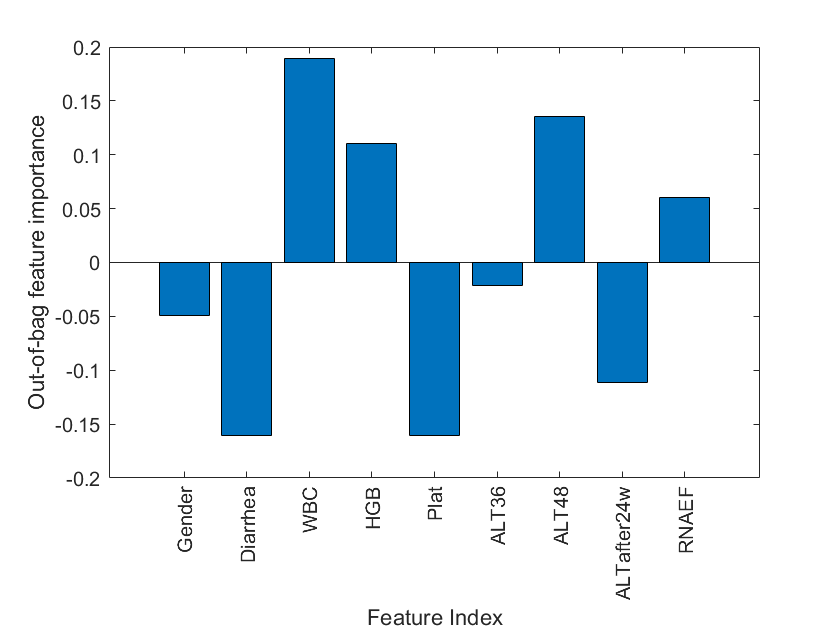

bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('Out-of-bag feature importance')
xticklabels(new_data.Properties.VariableNames(1:end))
xtickangle(90)

Ypred=predict(RFmodel,Xtest1) % RF gives output in cell array format

Ypred = 413×1 cell array
    {'15'}
    {'11'}
    {'4' }
    {'3' }
    {'15'}
    {'6' }
    {'14'}
    {'7' }
    {'15'}
    {'9' }
    {'12'}
    {'14'}
    {'11'}
    {'11'}
    {'12'}
    {'11'}
    {'11'}
    {'14'}
    {'6' }
    {'11'}
    {'11'}
    {'9' }
    {'15'}
    {'13'}
    {'6' }
    {'4' }
    {'4' }
    {'6' }
    {'14'}
    {'6' }


Ypred=categorical(Ypred) % cell array to categorical array

Ypred = 413×1 categorical array
     15 
     11 
     4 
     3 
     15 
     6 
     14 
     7 
     15 
     9 
     12 
     14 
     11 
     11 
     12 
     11 
     11 
     14 
     6 
     11 
     11 
     9 
     15 
     13 
     6 
     4 
     4 
     6 
     14 
     6 


sum(Ypred==Ytest1)/length(Ytest1) % accuracy

ans = 0.0823

confusionmat(double(Ytest1),double(Ypred))

Class List in given sample
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14


Total Instance = 413
class1==>1
class2==>2
class3==>3
class4==>4
class5==>5
class6==>6
class7==>7
class8==>8
class9==>9
class10==>10
class11==>11
class12==>12
class13==>13
class14==>14
Confusion Matrix
                      predict_class1    predict_class2    predict_class3    predict_class4    predict_class5    predict_class6    predict_class7    predict_class8    predict_class9    predict_class10    predict_class11    predict_class12    predict_class13    predict_class14
                      ______________    ______________    ______________    ______________

ans =      1     1     5     0     4     8     0     0     4     2     2     0     0     1
     1     9     3     0     2     5     0     0     2     1     0     0     1     0
     0     4     4     0     2     5     0     1     2     0     4     0     1     2
     0     4     1     0     1    17     0     0     0     2     3     0     0     0
     0     2     4     0     0     6     0     0     1     1     4     1     1     1
     0     2     3     3     5     5     0     0     5     1     1     0     0     0
     0     3     1     3     4    13     0     0     1     2     3     0     5     1
     1    10     2     1     2     4     0     0     0     1     1     2     1     1
     2     5     1     1     4     6     1     0     1     4     2     1     2     3
     0     8     4     0     1    12     0     1     2     4     1     0     2     2


x=fram_array(:,[1,3,11:27]);
y=categorical(fram_array(:,29));
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(x,y,0.7);
RFModel=TreeBagger(200,Xtrain1,Ytrain1,'Method','regression','OOBPrediction','on')

RFModel =   TreeBagger
Ensemble with 200 bagged decision trees:
                    Training X:             [964x19]
                    Training Y:              [964x1]
                        Method:           regression
                 NumPredictors:                   19
         NumPredictorsToSample:                    7
                   MinLeafSize:                    5
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []

  Properties, Methods


YPred=predict(RFModel,Xtest1)

YPred =     2.4975
    2.9671
    2.6753
    2.7535
    2.7331
    2.5823
    2.8351
    2.5729
    2.4984
    2.4999


corr(YPred,Ytest1)

ans = 0.0203

fram_array = table2array(fram1);
x=fram_array(:,1:27);
y=categorical(fram_array(:,29));
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(x,y,0.7);
RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [857x27]
                    Training Y:              [857x1]
                        Method:       classification
                 NumPredictors:                   27
         NumPredictorsToSample:                    6
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


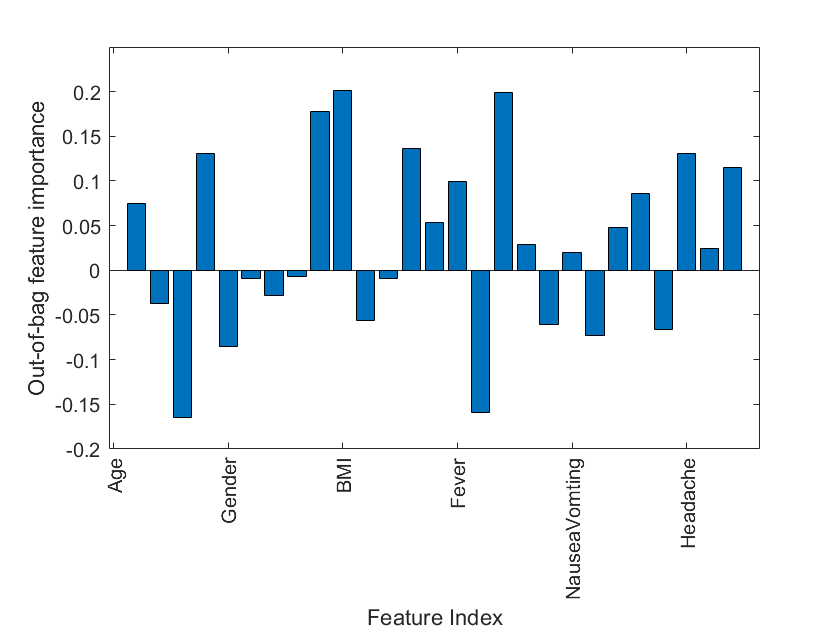

bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('Out-of-bag feature importance')
xticklabels(fram1.Properties.VariableNames(1:27))
xtickangle(90)

Ypred=predict(RFmodel,Xtest1) % RF gives output in cell array format

Ypred = 367×1 cell array
    {'4'}
    {'3'}
    {'4'}
    {'4'}
    {'3'}
    {'4'}
    {'3'}
    {'3'}
    {'3'}
    {'3'}
    {'4'}
    {'1'}
    {'1'}
    {'2'}
    {'4'}
    {'4'}
    {'1'}
    {'4'}
    {'3'}
    {'4'}
    {'4'}
    {'4'}
    {'1'}
    {'3'}
    {'3'}
    {'3'}
    {'3'}
    {'4'}
    {'4'}
    {'3'}


Ypred=categorical(Ypred) % cell array to categorical array

Ypred = 367×1 categorical array
     4 
     3 
     4 
     4 
     3 
     4 
     3 
     3 
     3 
     3 
     4 
     1 
     1 
     2 
     4 
     4 
     1 
     4 
     3 
     4 
     4 
     4 
     1 
     3 
     3 
     3 
     3 
     4 
     4 
     3 


sum(Ypred==Ytest1)/length(Ytest1) % accuracy

ans = 0.2425

confusionmat(double(Ytest1),double(Ypred))

Class List in given sample
     1
     2
     3
     4


Total Instance = 367
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          11                7                 34                33      
    Actual_class2          16                5                 30                45      
    Actual_class3          21                4                 30                41      
    Actual_class4          20                2                 25                43      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     11     7    34    33
    16     5    30    45
    21     4    30    41
    20     2    25    43


% Related variables -> dat(:,[2,13]) {Gender and HGB}


% Categorical 

% Find outliers
[data,tf]=rmoutliers(dat(:,[1,3,11:end]),1)
sum(tf(tf==1))